# Bioingeniería II - 2019-3

Ejercicio en calse

13 de marzo de 2020

# Objetivo

Identificar las características eléctricas de algunas señales EMG capturadas con electrodos superficiales.

# Actividades Propuestas:

Organizados en grupos de tres personas, procedan a desarrollar las actividades consignadas a continuación. El desarrollo de cada actividad debe registrarse en este mismo archivo. Al final de la clase deben enviar este archivo (en formato mlx) junto con su versión en pdf al correo: hilopezc@udistrital.edu.co.

## Actividad 1

Realicen la carga en MATLAB de la señal EMG de prueba. Considerando que la frecuencia de muestreo es de 200Hz, muestren todos los canales en un `subplot` de ocho filas, marcando los ejes con las escalas temporales adecuadas.

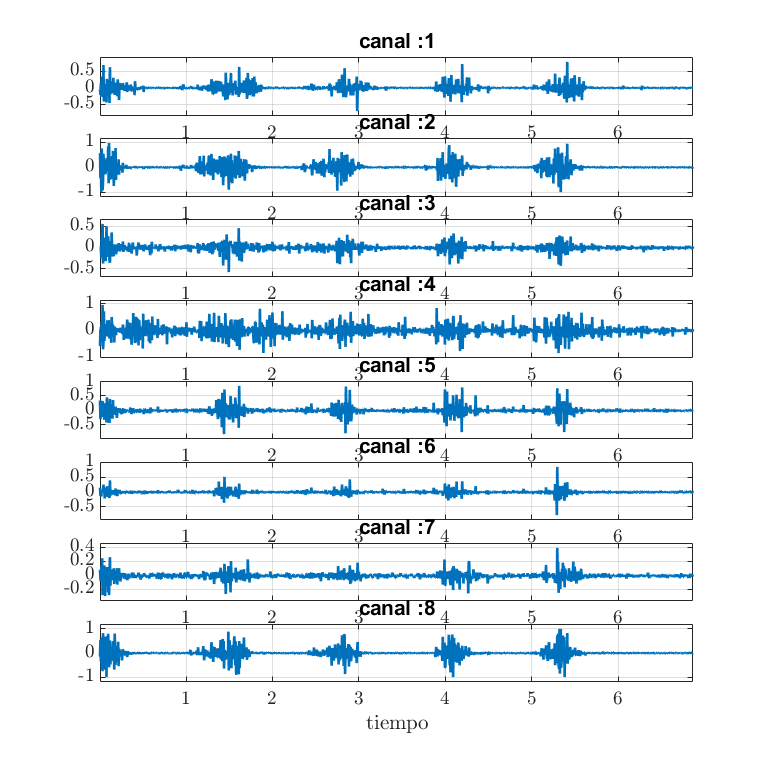

% Consignen aquí las instrucciones respectivas
a=load('emgprueba.mat');
a=a.G1juan;
time=(1:length(a))*1/200;
figure('renderer','painters',"Position",[50 50 800 800 ])
for i=1:8
    subplot(8,1,i);
    superplot(time,a(:,i),strcat("canal :",num2str(i)),'tiempo','',2);
end

## Actividad 2

Ahora, modifiquen la escala temporal para visualizar los potenciales de acción de las unidades motoras. ¿Se pueden identificar potenciales monofásicos, bifásicos o trifásicos? ¿Se pueden identificar los picos etiquetados como *turns*?

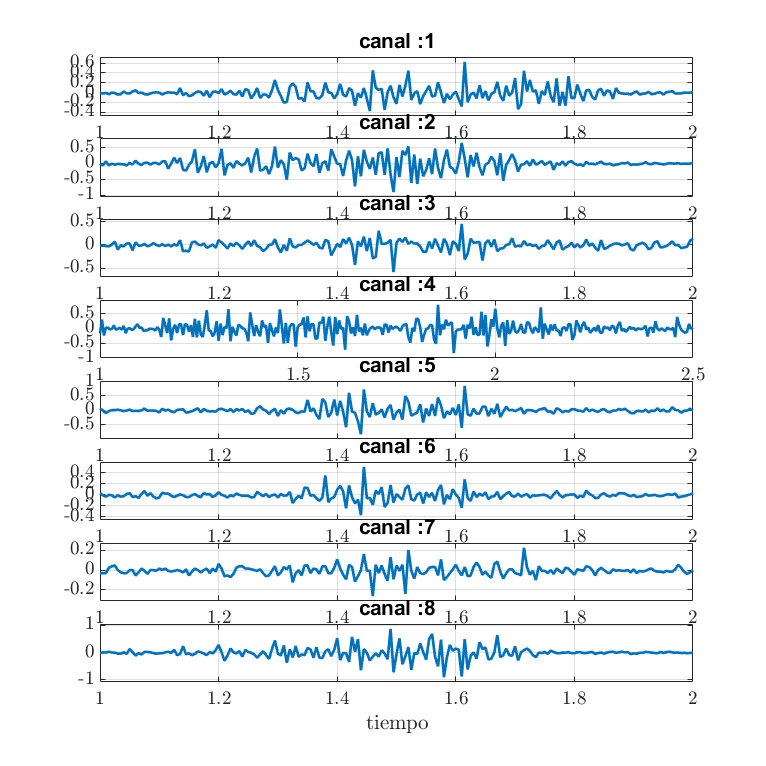

figure('renderer','painters',"Position",[50 50 800 800 ])
for i=1:8
    if i==4
    subplot(8,1,i);
    superplot(time(200:500),a(200:500,i),strcat("canal :",num2str(i)),'tiempo','',2);
    else
        subplot(8,1,i);
        superplot(time(200:400),a(200:400,i),strcat("canal :",num2str(i)),'tiempo','',2);
    end
end

## Actividad 3

Utilicen la `fft` para obtener el espectro positivo de cada uno de los canales de la señal de prueba. ¿Cuánto es el ancho de banda de la señal capturada?

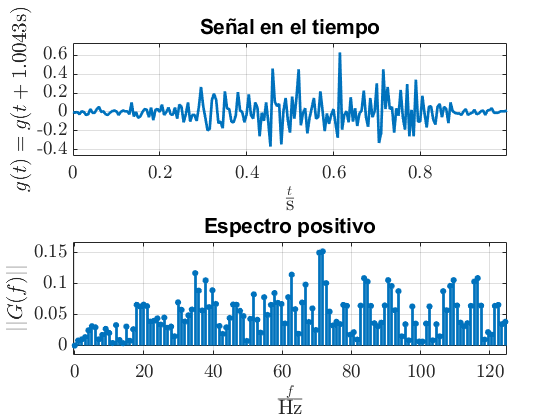

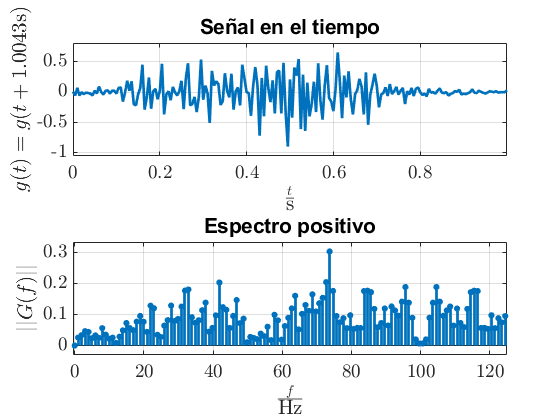

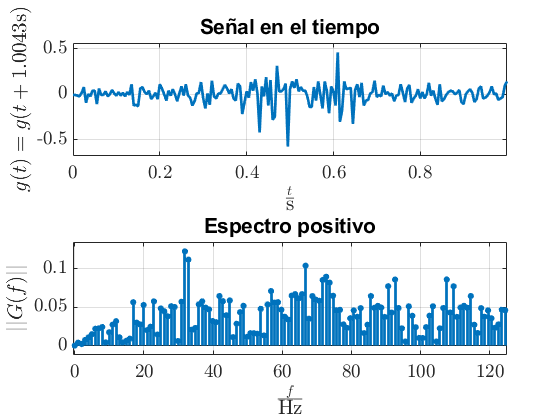

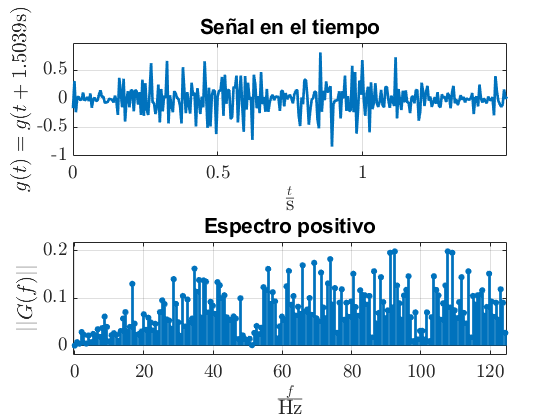

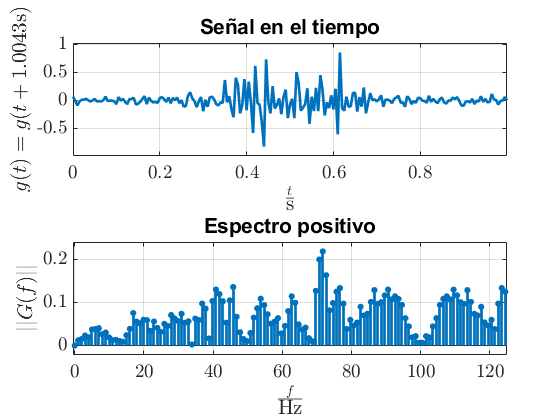

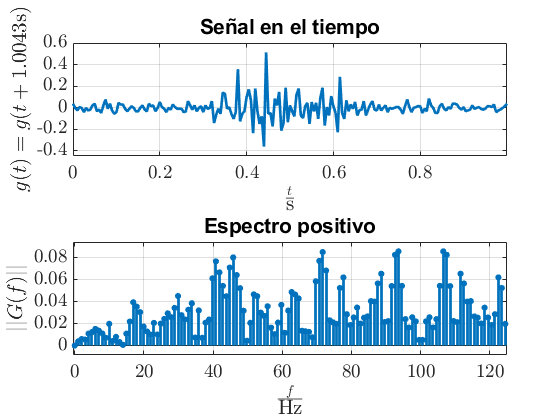

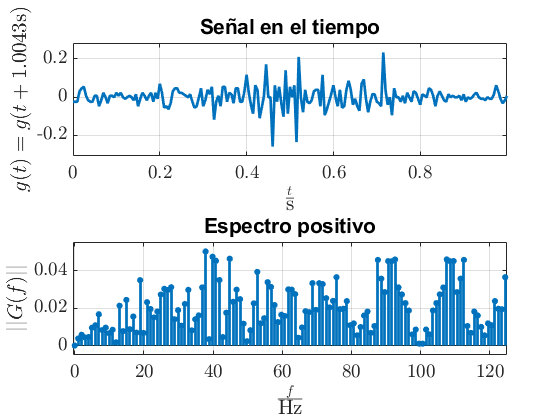

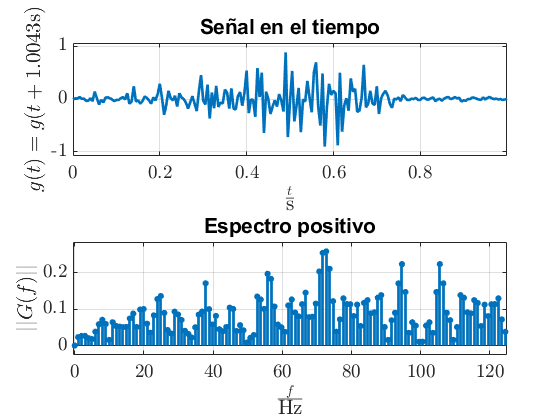

for i=1:8
    figure()
    if i==4
        rango=200:500;
        espectrofftJDR([time',a(:,i)],1,125,rango);
    else
        rango=200:400;
        espectrofftJDR([time',a(:,i)],1,125,rango);
    end 
end

# Conclusiones

% Redacten en esta sección las conclusiones que obtuvieron del ejercicio.